**Problem 1**

Part 1a

Let's tackle *A* first.  To find the spectral radius, we need to find the eigenvalues.

A = [0 1;3 -2];
[V,D] = eig(A);
rho = max(max(abs(D)))  %This computes the spectral radius

rho = 3

Now find the other norms using the definitions.  I put the corresponding "norm" commands in to check.

fro = sqrt(trace(A*A'))  %Using the definition

fro = 3.7417

%fro = norm(A,'fro') %Using norm
n1 = max(abs(A(1,1))+abs(A(2,1)),abs(A(1,2))+abs(A(2,2)))  %Very brute force

n1 = 3

%n1 = norm(A,1)
ninf = max(abs(A(1,1))+abs(A(1,2)),abs(A(2,1))+abs(A(2,2)))

ninf = 5

%ninf = norm(A,'inf')
[U,S,D] = svd(A);
n2 = S(1,1)

n2 = 3.6503

%n2 = norm(A,2)

As expected, all norms are larger than the spectral radius.  Now repeat for $B$.

B = [0 1;3 0];
[V,D] = eig(B);
rho = max(max(abs(D)))  %This computes the spectral radius

rho = 1.7321

fro = sqrt(trace(B*B'))  %Using the definition

fro = 3.1623

%fro = norm(B,'fro') %Using norm
n1 = max(abs(B(1,1))+abs(B(2,1)),abs(B(1,2))+abs(B(2,2)))  %Very brute force

n1 = 3

%n1 = norm(B,1)
ninf = max(abs(B(1,1))+abs(B(1,2)),abs(B(2,1))+abs(B(2,2)))

ninf = 3

%ninf = norm(B,'inf')
[U,S,D] = svd(B);
n2 = S(1,1)

n2 = 3

%n2 = norm(B,2)

For this matrix the spectral radius is nowhere near the size of the norms!  This is why eigenvalues are a poor measure of gain.

Part 1b

The properties can be quickly verified as follows:

1.)  $\|A\|_\max$ is clearly $\geq0
$ for all non-zero *A* and is clearly = 0 for *A = *0.

2.)  When multiplying *A* by a scalar *c*, each element of *A* is simply given by $ca_{ij}$.  Clearly $|ca_{ij}| = |c||a_{ij}|\Rightarrow\max(|ca_{ij}|) = |c|\max|a_{ij}|.$  Therefore $\|cA\|_\max = |c|\|A\|_{\max}$.

3.)  Consider scalars *a* and *b.  *It is clear that $|a+b|\leq|a|+|b|$ (absolute value is a norm for scalars).  Let *ij* be the index at which $\|A+B||_\max$ occurs.  Then $|a_{ij}+b_{ij}|\leq |a_{ij}|+|b_{ij}|$,  which directly implies that $\max|a_{ij}+b_{ij}|\leq \max|a_{ij}|+\max|b_{ij}|$, or $\|A+B\|_\max\leq\|A\|_\max+\|B\|_\max$.

There are infinitely many counterexamples, but two that come to mind are

$A = \pmatrix{1 & 1 \cr 1 & 1}$:  $\|A\|_\max = 1$ and $\rho(A) = 2$

$A = \pmatrix{ 1 & 0 \cr a & 1}, B = \pmatrix{1 & a \cr 0 & 1}$:  $\|AB\|_\max = a^2+1$ and $\|A\|_\max\|B\|_\max = a^2$

Part 1c

Note that the all-pass filter and the time delay both satisfy $|Q(j\omega)| = 1\forall\omega$.  So we can prove both at once by showing that the norms are invariant to any such *Q*.  Let's start with the infinity norm.


$$\|QG\|_\infty = \max_\omega|QG| = \max_\omega|Q||G| $$


Because for the two systems of interest $|Q| =1\forall\omega$, this results in


$$\|QG\|_\infty = \max_\omega|G| = \|G\|_\infty$$


The result for the 2-norm is quite similar.


$$\|QG\|_2 = \left(\frac{1}{2\pi}\int_{-\infty}^\infty|QG|^2d\omega\right)^{1/2} = \left(\frac{1}{2\pi}\int_{-\infty}^\infty|Q|^2|G|^2d\omega\right)^{1/2}$$


Because $|Q| = 1\forall\omega$,


$$\|QG\|_2 = \left(\frac{1}{2\pi}\int_{-\infty}^\infty|G|^2d\omega\right)^{1/2} = \|G\|_2$$


**Problem 2**

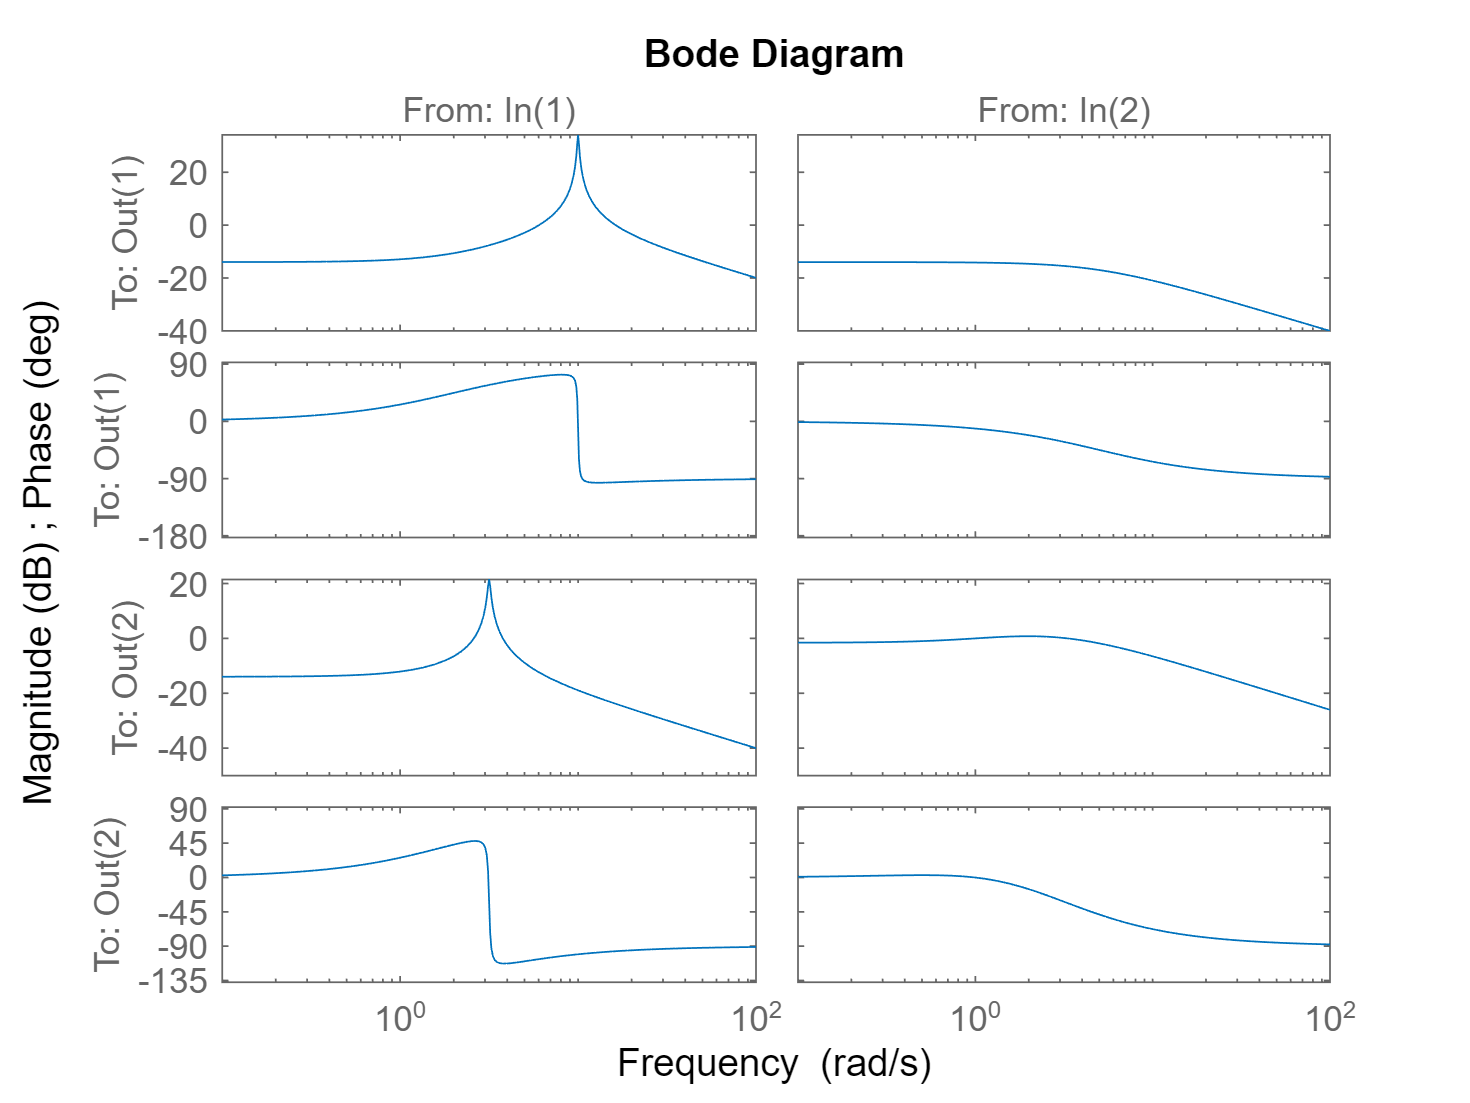

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100) 1/(s+5); (s+2)/(s^2+0.1*s+10) 5*(s+1)/(s+2)/(s+3)];
bode(G)

Part 2a

G_inv_improper = inv(G)

G_inv_improper =
 
  From input 1 to output...
       0.102 s^6 + 0.6429 s^5 + 11.92 s^4 + 68.74 s^3 + 165.5 s^2 + 618.4 s + 510.2
   1:  ----------------------------------------------------------------------------
                s^5 + 8.118 s^4 + 25.97 s^3 + 78.98 s^2 + 141.8 s + 77.55
 
       -0.02041 s^6 - 0.249 s^5 - 3.131 s^4 - 26.58 s^3 - 105.7 s^2 - 188 s - 122.4
   2:  ----------------------------------------------------------------------------
                s^5 + 8.118 s^4 + 25.97 s^3 + 78.98 s^2 + 141.8 s + 77.55
 
  From input 2 to output...
       -0.02041 s^6 - 0.1082 s^5 - 2.398 s^4 - 11.51 s^3 - 35.1 s^2 - 103.5 s - 122.4
   1:  ------------------------------------------------------------------------------
                 s^5 + 8.118 s^4 + 25.97 s^3 + 78.98 s^2 + 141.8 s + 77.55
 
       0.2041 s^6 + 2.469 s^5 + 12.69 s^4 + 44.31 s^3 + 118.2 s^2 + 189 s + 122.4
   2:  --------------------------------------------------------------------------
               s^5 + 8.1

Unsurprisingly, each entry of the inverse is improper.  Given the desired crossover frequency of 100 rad/s, we can safely add poles to each entry at 10,000 rad/s without changing the behavior overall.

G_inv = 1/(s/10000+1)*G_inv_improper

G_inv =
 
  From input 1 to output...
                                                                                      
       1020 s^6 + 6429 s^5 + 1.192e05 s^4 + 6.874e05 s^3 + 1.655e06 s^2 + 6.184e06 s  
                                                                                      
                                                                            + 5.102e06
                                                                                      
   1:  -------------------------------------------------------------------------------
                                                                                      
       s^6 + 1.001e04 s^5 + 8.121e04 s^4 + 2.598e05 s^3 + 7.899e05 s^2 + 1.418e06 s   
                                                                                      
                                                                            + 7.755e05
                                                                                      
 
   

Now getting the desired loopshapes is trivial - we are effectively controlling the identity matrix, and hence we can simply put the desired loop shapes on the diagonal.

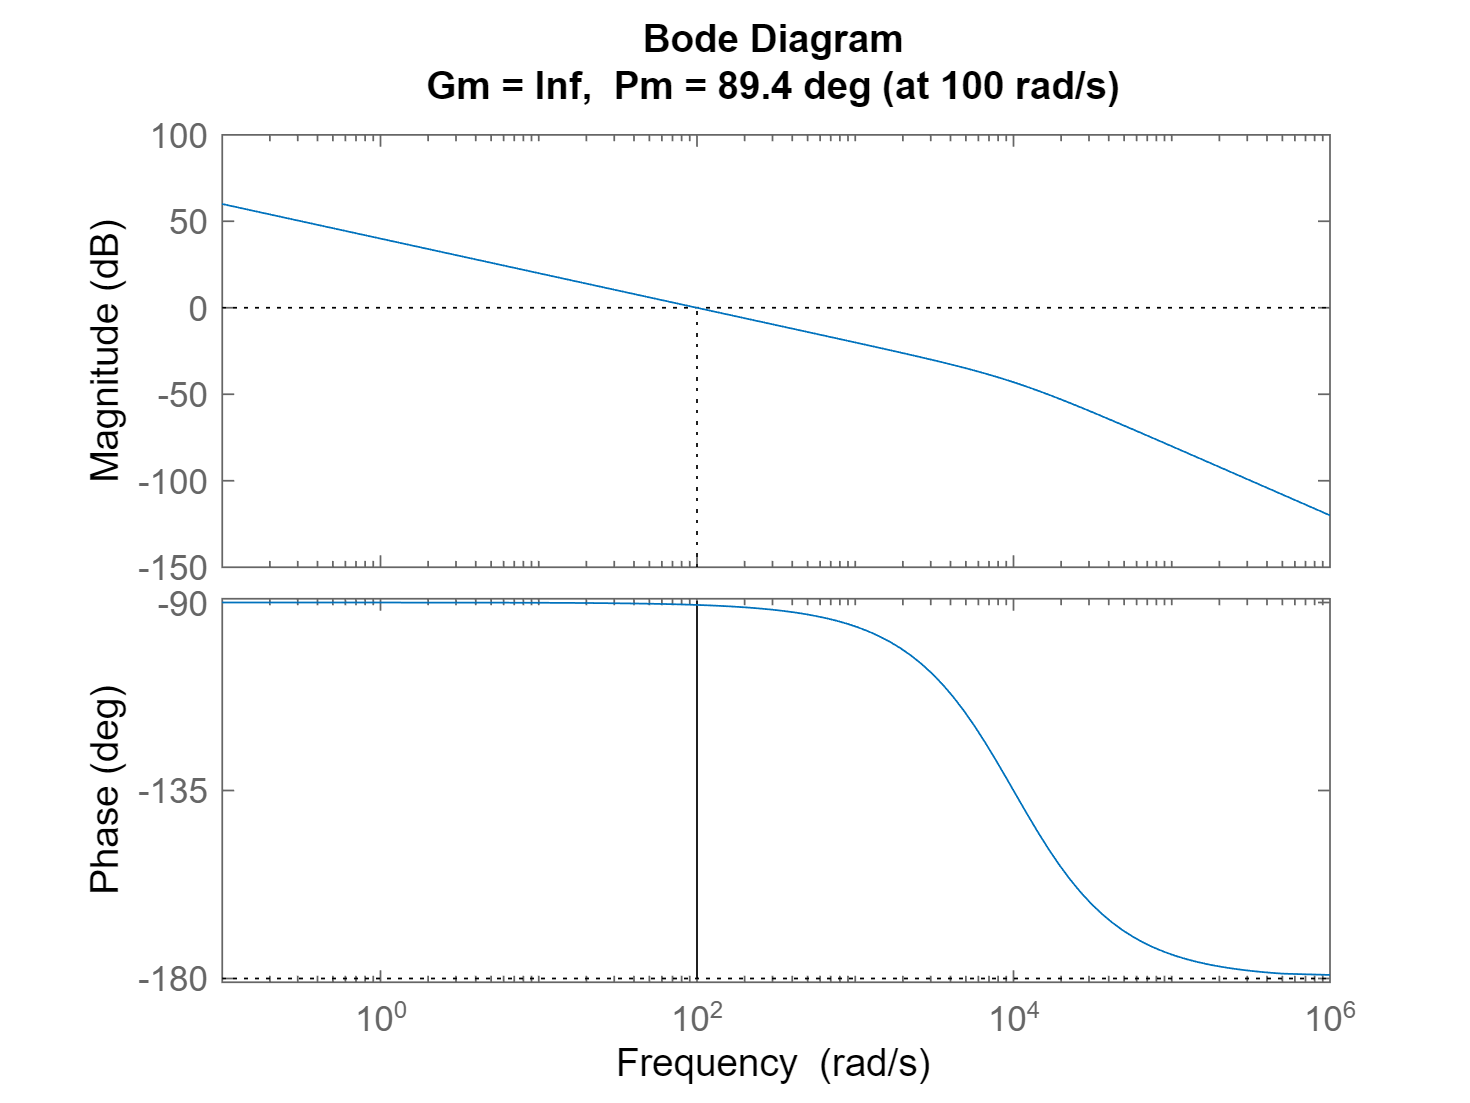

K = G_inv*[100/s 0;0 100/s];
L = minreal(G*K);
margin(L(1,1))

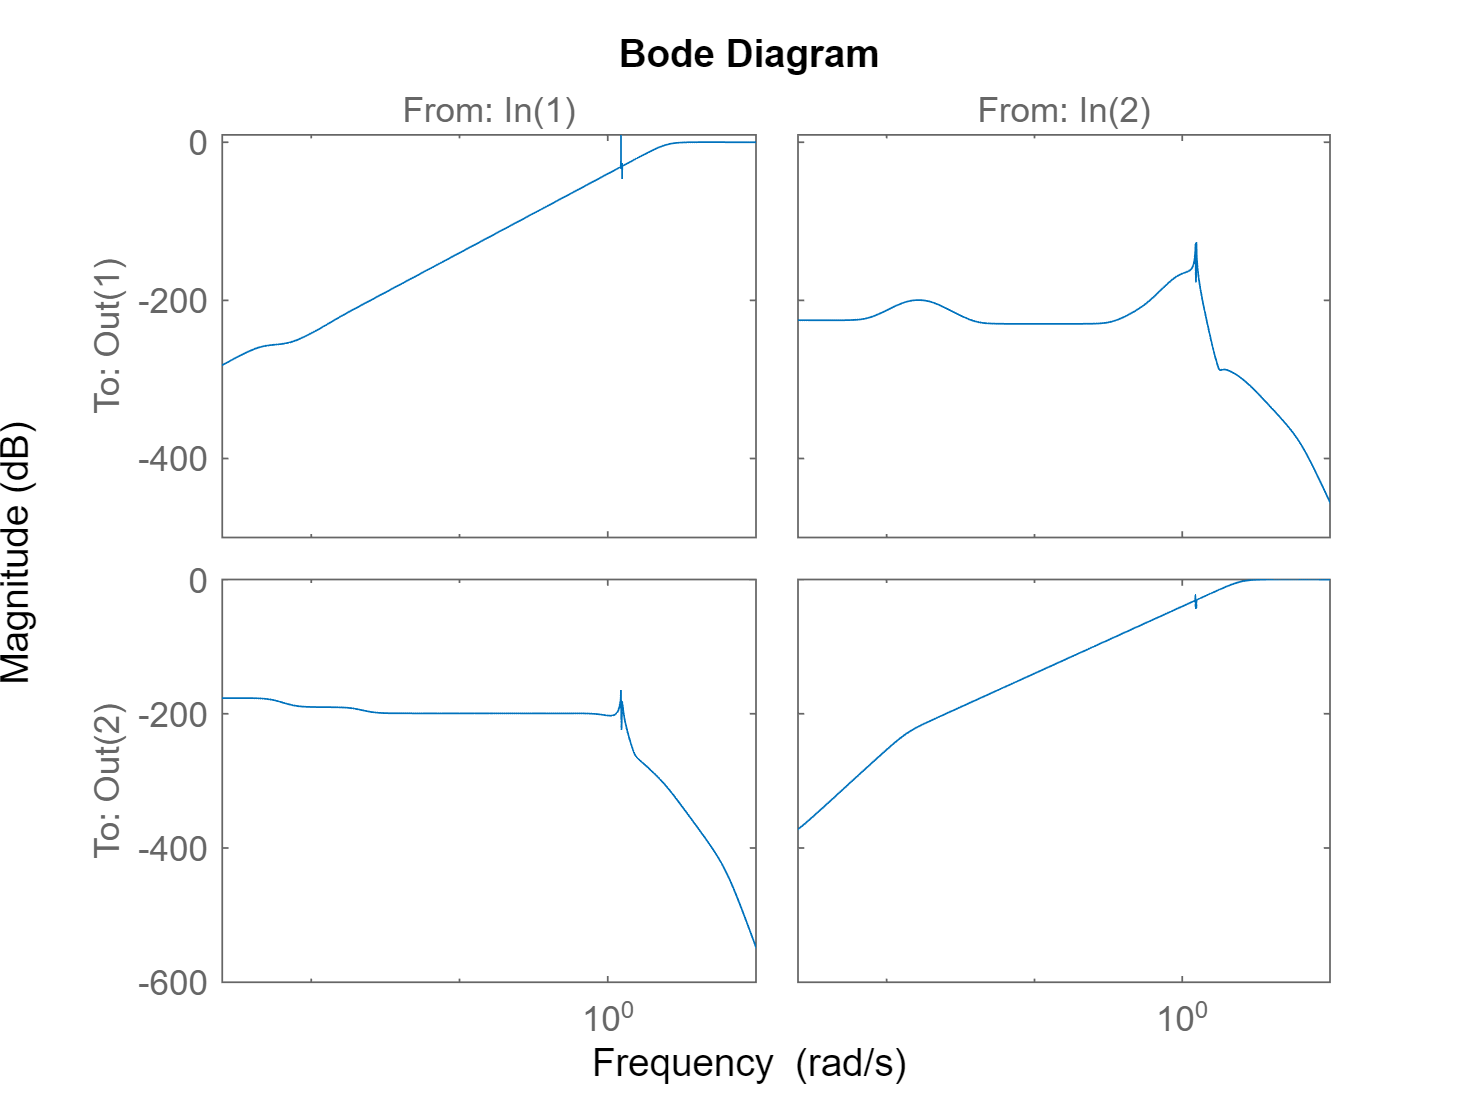

S = inv(eye(2)+L);
bodemag(S)

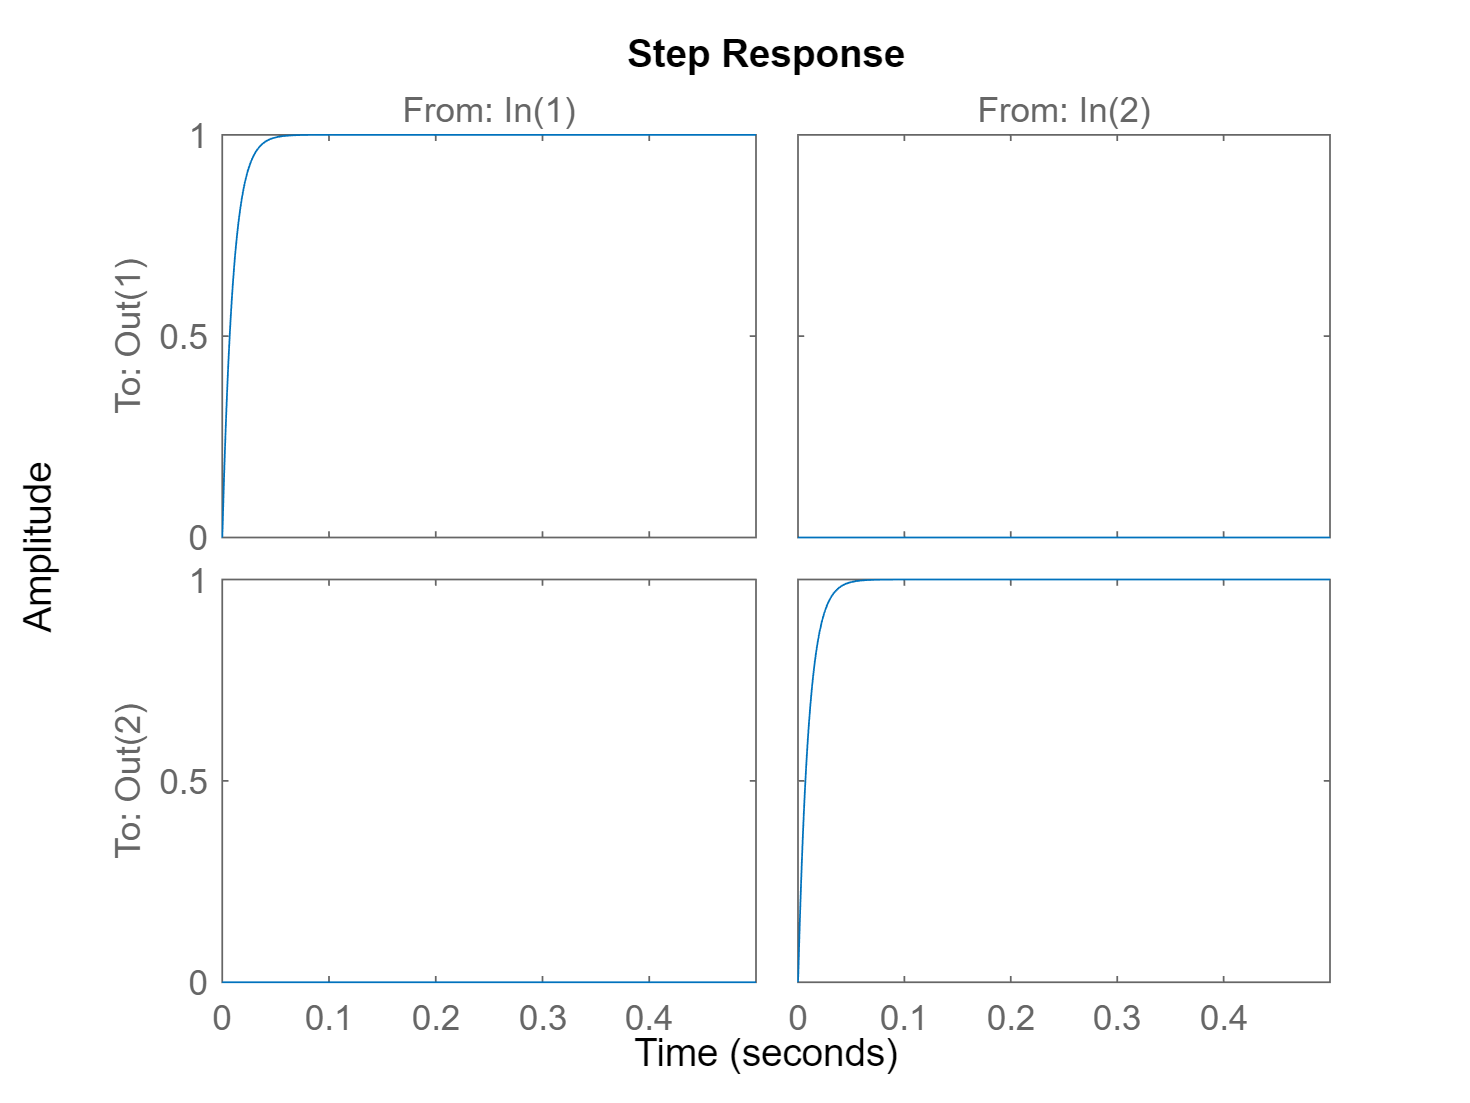

step(eye(2)-S,0.5)

Part 2b

This is a classic mixed synthesis problem.  Here I'll use bisection again to maximize crossover; the actuation penalty is constant whereas the others change with crossover frequency.

Wu = [1/100 0;0 1/100];
wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    Wp = [Wp 0;0 Wp];
    Wt = makeweight(1/1.5,3*w_try,1000);
    Wt = [Wt 0;0 Wt];
    [K,CL,GAM] = mixsyn(G,Wp,Wu,Wt);
    if GAM<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
w_opt = w_try

w_opt = 331.5487

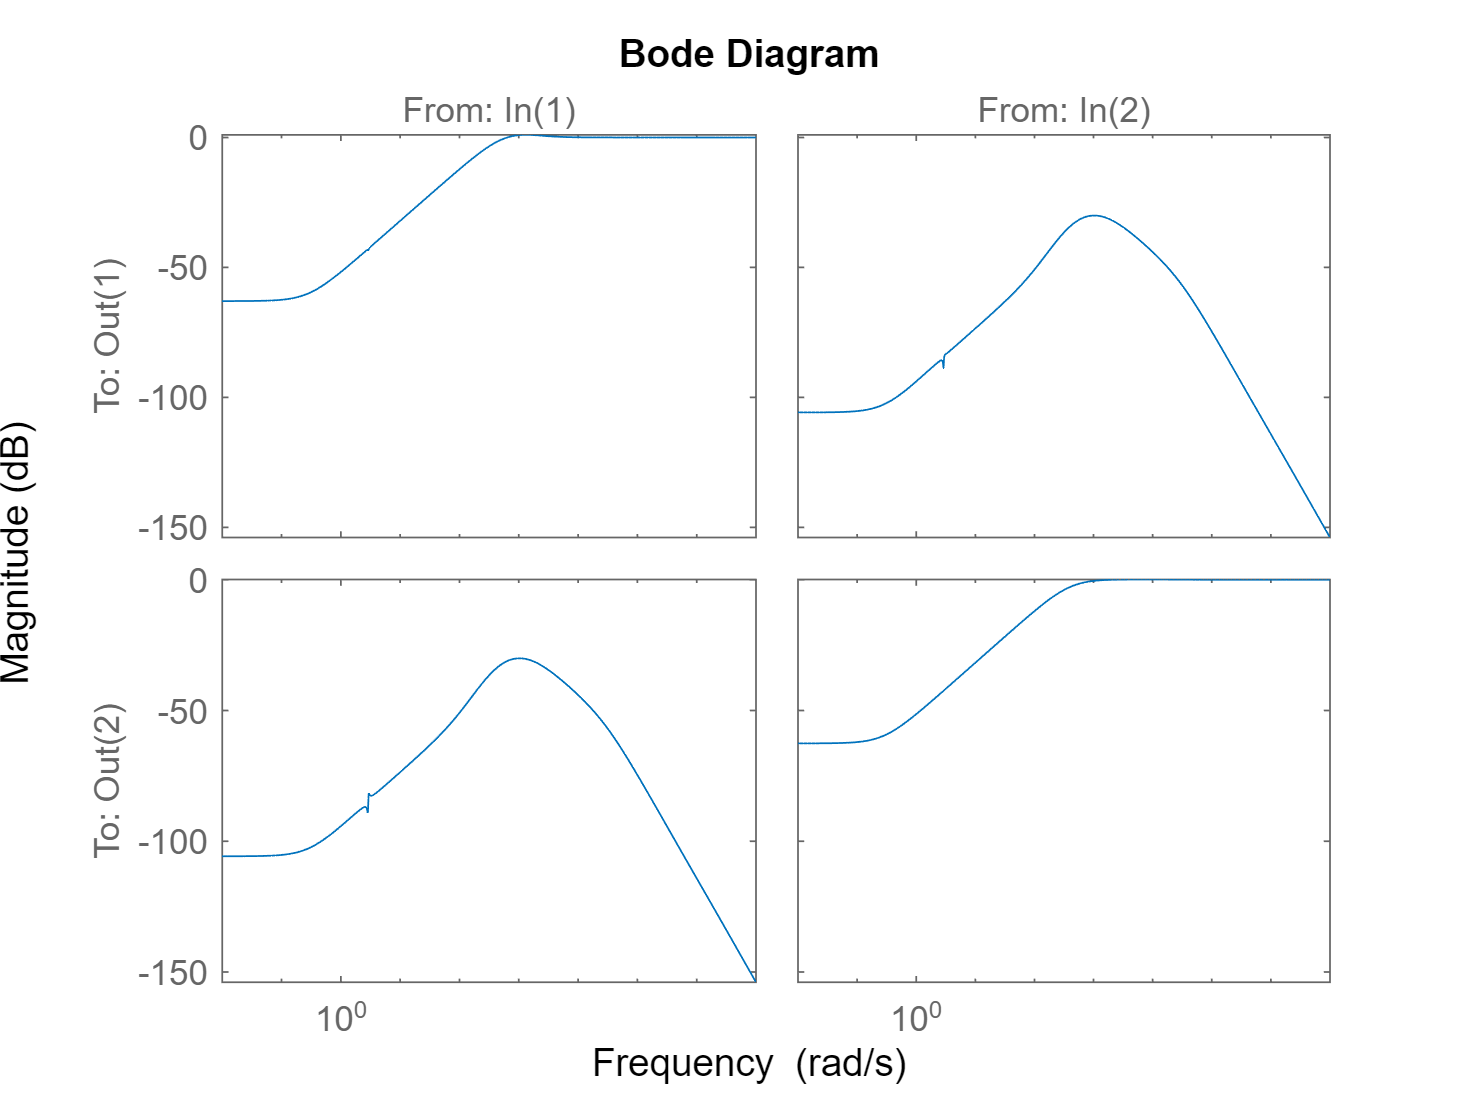

L = G*K;
T = feedback(L,eye(2));
S = eye(2)-T;
bodemag(S)

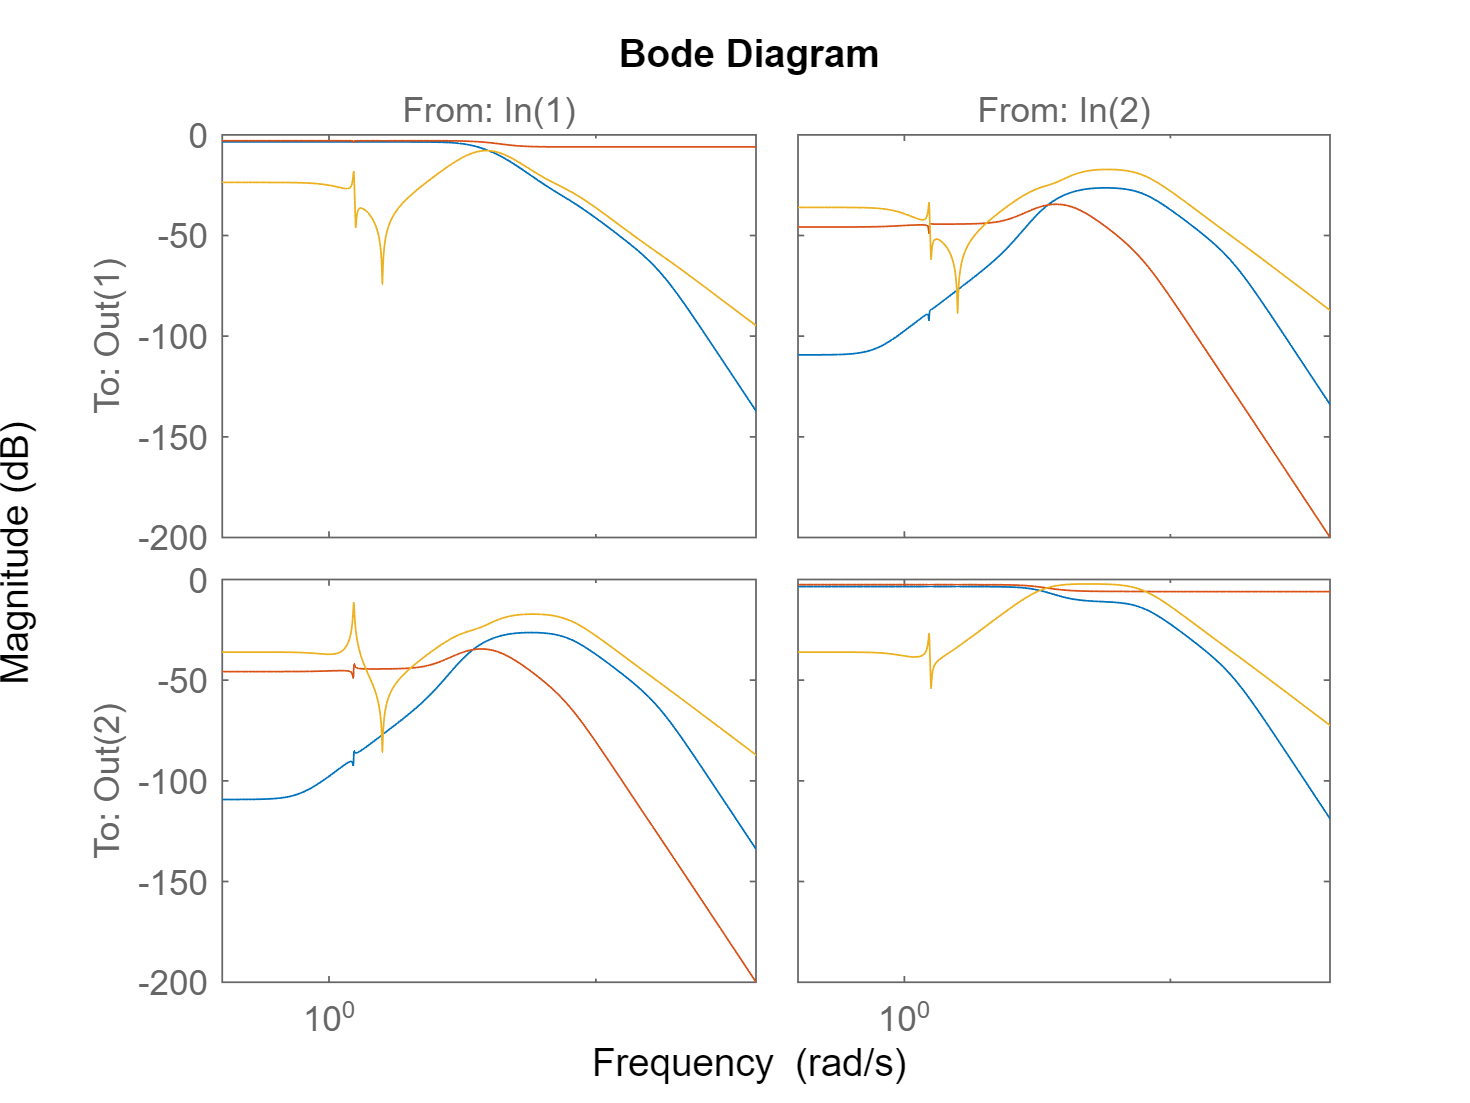

R = K*S;
bodemag(Wt*T,Wp*S,Wu*R)

**Problem 3**

Part 3a

Firstly I want to collapse the dashed line region into an equivalent plant $G^\star$.  Quick block diagram algebra shows that $G^\star = G(I+\Delta W_\Delta)$.  Start this as a set of equations, then build the $P$ matrix from those.


$$z_u = W_u u$$



$$z_y = W_p(G^\star u-Mr)$$



$$v = \pmatrix{-G^\star u-W_nn \cr r}$$


Now, using $w = \pmatrix{r & n}^T$ and $z = \pmatrix{z_u & z_y}^T$ results in 


$$P = \pmatrix{0&0&W_u \cr  -W_pM & 0 & W_pG^\star \cr  0 & -W_n & -G^\star \cr  I & 0 & 0}$$


To find $N$, use the formula for a lower LFT:


$$N = \pmatrix{ 0&0 \cr  -W_pM & 0}+\pmatrix{ W_u \cr W_pG^\star}\pmatrix{K_1 & K_2}\left(I-\pmatrix{-G^\star \cr 0}\pmatrix{K_1 & K_2}\right)^{-1}\pmatrix{ 0 & -W_n  \cr I & 0}$$


Look at the inverse term:  $\left(I-\pmatrix{-G^\star K_1 & -G^\star K_2 \cr 0 & 0 }\right)^{-1} = \pmatrix{I+G^\star K_1 & G^\star K_2 \cr 0 & I}^{-1} = \left(I+G^\star K_1\right)^{-1}\pmatrix{I & -G^\star K_2 \cr 0 & I+G^\star K_1}$$

Now define $S_1 = (I+G^\star K_1)^{-1}$ and multiply by the right-most matrix


$$N =  \pmatrix{0&0 \cr  -W_pM & 0}+\pmatrix{ W_u \cr W_pG}\pmatrix{K_1 & K_2}\pmatrix{ -S_1GK_2 & -S_1W_n \cr  I & 0}$$
 

This simplifies to


$$N = \pmatrix{  W_u\left(I-K_1S_1G\right)K_2 & -W_u K_1S_1W_n \cr  W_p\left(G\left(I-K_1S_1G\right)K_2-M) & -W_pGK_1S_1W_n}$$


Part 3b

This one is practically right out of the example script.

systemnames = 'G Wp Wu Wt'

systemnames = 'G Wp Wu Wt'

Now we have to define the inputs and outputs to the system by giving values to *inputvar* and *outputvar*.

inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;Wt;r-G]'; %Strangely, the system outputs are just the name

Here the variables are partitioned as before, i.e. the input variables are listed as $[w ,u]^T$.  Now we need to give the inputs to each system.

input_to_G = '[u]';
input_to_Wp = '[r-G]';
input_to_Wu = '[u]';
input_to_Wt = '[G]';

That's the requirements!  Now we put it in action.

cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

Now let's test to see that it worked...

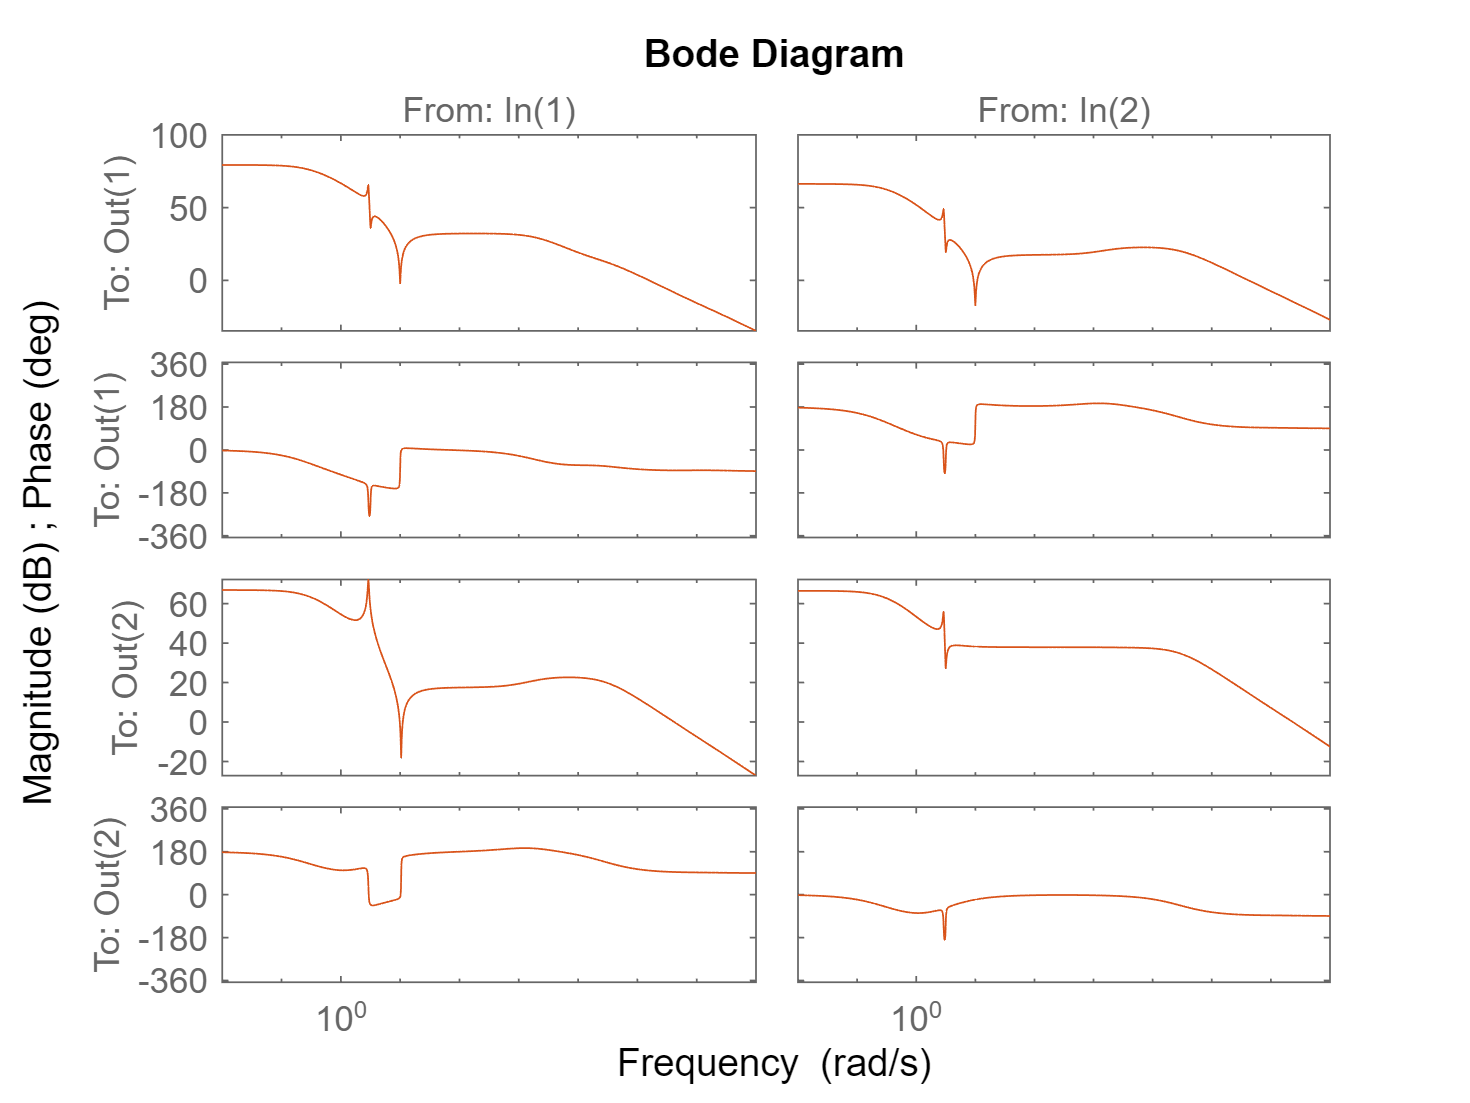

[Kms,CL,GAM] = mixsyn(G,Wp,Wu,Wt);
[Khinf,CL,GAM] = hinfsyn(P,2,2);
bode(Kms,Khinf)  %They're on top!

Part 3c

This already has the look of an LFT in structure.  For a lower LFT


$$F_l\left(H,\frac{1}{s}\right) = H_{11}+H_{12}\frac{1}{s}\left(I-H_{22}\frac{1}{s}\right)^{-1}H_{21}$$


Now, noting that $(cA)^{-1} = c^{-1}A^{-1}$ for $c$ a scalar and choosing $c = s$ and $A = \left(I-H_{22}\frac{1}{s}\right)$, we have


$$F_l\left(H,\frac{1}{s}\right) = H_{11}+H_{12}\left(sI-H_{22}\right)^{-1}H_{21}$$


This is now basically done, and by inspection


$$H = \pmatrix{D & C \cr B & A}$$
